# Throughput performance degration due to interference

clear;
clc;
close all;

## Setup the initial parameters and file paths

NumCandidateRelays = [1152, 2384, 3644];
NumCandidateRelaysString = ["1152","2384","3644"];
BeamWidth = [5,7,9,11,13,15];
DataClass = ["Capacity","Paths","Sequence"];
% PathResult1Mbs = '../../Data/Paths/Single_MBS/200/';
% PathResult2Mbs = '../../Data/Paths/Double_MBS/200/';
PathResult1Mbs300m = '../../Data/Throughput_Comparison/Single_MBS/300/ZeroISO/';
% PathResult2Mbs300m = '../../Data/Paths/Double_MBS/300/';
% PathResult1MbsLA = '../../Data/Paths/Single_MBS_LimitedArea/200/';
% PathResult2MbsLA = '../../Data/Paths/Double_MBS_LimitedArea/200/';
% PathResultBench = '../../Data/Paths/Idp/';

Data = ReadThroughputComparisonData(PathResult1Mbs300m);


## Get the percentage information

percentageData0 = Data(1:100,1:25,3);
percentageData0 = reshape(percentageData0,1,100*25);
percentageData0 = percentageData0(percentageData0~=0).*100;
oldThData0 = Data(1:100,1:25,1);
oldThData0 = reshape(oldThData0,1,100*25);
oldThData0 = oldThData0(oldThData0~=0);
avg_OldThData0 = mean(oldThData0);
newThData0 = Data(1:100,1:25,2);
newThData0 = reshape(newThData0,1,100*25);
newThData0 = newThData0(newThData0~=0);
avg_NewThData0 = mean(newThData0);

percentageData5 = Data(101:200,1:25,3);
percentageData5 = reshape(percentageData5,1,100*25);
percentageData5 = percentageData5(percentageData5~=0).*100;
oldThData5 = Data(101:200,1:25,1);
oldThData5 = reshape(oldThData5,1,100*25);
oldThData5 = oldThData5(oldThData5~=0);
avg_OldThData5 = mean(oldThData5);
newThData5 = Data(101:200,1:25,2);
newThData5 = reshape(newThData5,1,100*25);
newThData5 = newThData5(newThData5~=0);
avg_NewThData5 = mean(newThData5);

percentageData10 = Data(201:300,1:25,3);
percentageData10 = reshape(percentageData10,1,100*25);
percentageData10 = percentageData10(percentageData10~=0).*100;
oldThData10 = Data(201:300,1:25,1);
oldThData10 = reshape(oldThData10,1,100*25);
oldThData10 = oldThData10(oldThData10~=0);
avg_OldThData10 = mean(oldThData10);
newThData10 = Data(201:300,1:25,2);
newThData10 = reshape(newThData10,1,100*25);
newThData10 = newThData10(newThData10~=0);
avg_NewThData10 = mean(newThData10);

percentageData15 = Data(301:400,1:25,3);
percentageData15 = reshape(percentageData15,1,100*25);
percentageData15 = percentageData15(percentageData15~=0).*100;
oldThData15 = Data(301:400,1:25,1);
oldThData15 = reshape(oldThData15,1,100*25);
oldThData15 = oldThData15(oldThData15~=0);
avg_OldThData15 = mean(oldThData15);
newThData15 = Data(301:400,1:25,2);
newThData15 = reshape(newThData15,1,100*25);
newThData15 = newThData15(newThData15~=0);
avg_NewThData15 = mean(newThData15);

percentageData20 = Data(401:500,1:25,3);
percentageData20 = reshape(percentageData20,1,100*25);
percentageData20 = percentageData20(percentageData20~=0).*100;
oldThData20 = Data(401:500,1:25,1);
oldThData20 = reshape(oldThData20,1,100*25);
oldThData20 = oldThData20(oldThData20~=0);
avg_OldThData20 = mean(oldThData20);
newThData20 = Data(401:500,1:25,2);
newThData20 = reshape(newThData20,1,100*25);
newThData20 = newThData20(newThData20~=0);
avg_NewThData20 = mean(newThData20);

## Get the distribution of hop number of each logical link

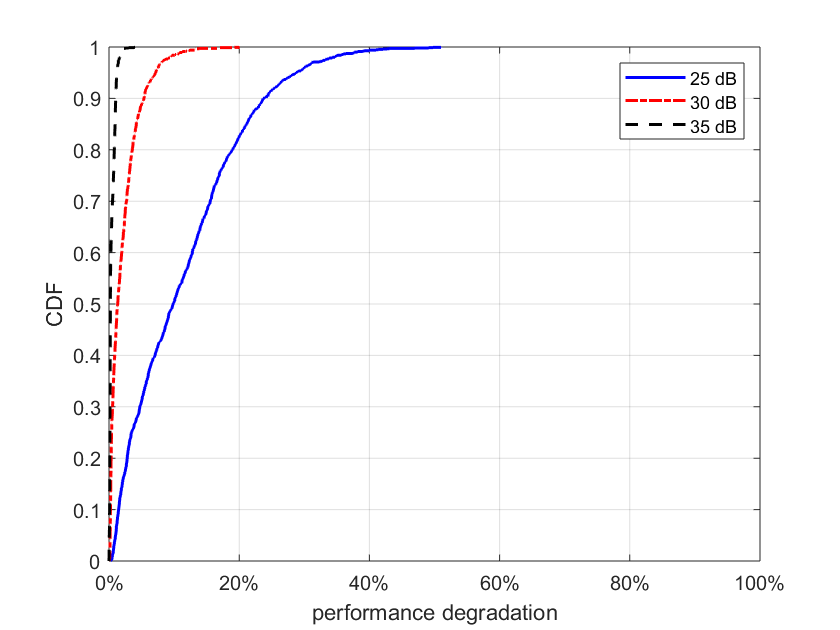

figure;
h(1,1) = cdfplot(percentageData5);hold on;
h(1,2) = cdfplot(percentageData10);
h(1,3) = cdfplot(percentageData15);
% h(1,4) = cdfplot(percentageData15);
% h(1,5) = cdfplot(percentageData20);

set( h(1,1), 'LineStyle', '-', 'Color', 'b','LineWidth',1.5);
xtickformat('percentage');
xlim([0 100]);
set( h(1,2), 'LineStyle', '-.', 'Color', 'r','LineWidth',1.5);
set( h(1,3), 'LineStyle', '--', 'Color', 'k','LineWidth',1.5);
% set( h(1,4), 'LineStyle', ':', 'Color', 'k','LineWidth',1.5);
% set( h(1,5), 'LineStyle', '-', 'Color', 'k','LineWidth',.5);
% hopNumCount_0 = [];
% hopNumCount_1 = [];
% hopNumCount_2 = [];
% hopNumCount_3 = [];
% hopNumCount_4 = [];
% for i = 1:length(name_2_9)
%     filename = pathname + name_2_9(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
%     hopNumCount_0 = [hopNumCount_0, sum(data(2,:)==0)];
%     hopNumCount_1 = [hopNumCount_1, sum(data(2,:)==1)];
%     hopNumCount_2 = [hopNumCount_2, sum(data(2,:)==2)];
%     hopNumCount_3 = [hopNumCount_3, sum(data(2,:)==3)];
%     hopNumCount_4 = [hopNumCount_4, sum(data(2,:)==4)];
% end
% hopNumCount_0 = hopNumCount_0'./pathNum_name_2_9;
% hopNumCount_1 = hopNumCount_1'./pathNum_name_2_9;
% hopNumCount_2 = hopNumCount_2'./pathNum_name_2_9;
% hopNumCount_3 = hopNumCount_3'./pathNum_name_2_9;
% hopNumCount_4 = hopNumCount_4'./pathNum_name_2_9;
% h(2,1) = cdfplot(hopNumCount_0');hold on;
% h(2,2) = cdfplot(hopNumCount_1');
% h(2,3) = cdfplot(hopNumCount_2');
% h(2,4) = cdfplot(hopNumCount_3');
% h(2,5) = cdfplot(hopNumCount_4');
% set( h(2,1), 'LineStyle', '-', 'Color', 'b','LineWidth',1.5);
% set( h(2,2), 'LineStyle', '-.', 'Color', 'g','LineWidth',1.5);
% set( h(2,3), 'LineStyle', '--', 'Color', 'r','LineWidth',1.5);
% set( h(2,4), 'LineStyle', ':', 'Color', 'c','LineWidth',1.5);
legend('25 dB','30 dB', '35 dB');
% legend('1-hop, low density','2-hop, low density','3-hop, low density','4-hop, low density',...
%     '5-hop, low density','1-hop, high density','2-hop, high density','3-hop, high density','4-hop, high density','5-hop, high density');
title '';
xlabel('performance degradation');
ylabel('CDF');

% annotation('textarrow',[0.6214 0.5553],[0.5786 0.5786],'String','')
% annotation('textarrow',[0.3554 0.4018],[0.6333 0.6333],'String','')
% annotation('textarrow',[0.1571 0.2054],[0.6762 0.6762],'String','')


PathResult1Mbs300m = '../../Data/Throughput_Comparison/Single_MBS/300/NoiseISO/';
% PathResult2Mbs300m = '../../Data/Paths/Double_MBS/300/';
% PathResult1MbsLA = '../../Data/Paths/Single_MBS_LimitedArea/200/';
% PathResult2MbsLA = '../../Data/Paths/Double_MBS_LimitedArea/200/';
% PathResultBench = '../../Data/Paths/Idp/';

Data = ReadThroughputComparisonData(PathResult1Mbs300m);


## Get the percentage information

percentageData0 = Data(1:100,1:25,3);
percentageData0 = reshape(percentageData0,1,100*25);
percentageData0 = percentageData0(percentageData0~=0).*100;
oldThData0 = Data(1:100,1:25,1);
oldThData0 = reshape(oldThData0,1,100*25);
oldThData0 = oldThData0(oldThData0~=0);
avg_OldThData0 = mean(oldThData0);
newThData0 = Data(1:100,1:25,2);
newThData0 = reshape(newThData0,1,100*25);
newThData0 = newThData0(newThData0~=0);
avg_NewThData0 = mean(newThData0);

percentageData5 = Data(101:200,1:25,3);
percentageData5 = reshape(percentageData5,1,100*25);
percentageData5 = percentageData5(percentageData5~=0).*100;
oldThData5 = Data(101:200,1:25,1);
oldThData5 = reshape(oldThData5,1,100*25);
oldThData5 = oldThData5(oldThData5~=0);
avg_OldThData5 = mean(oldThData5);
newThData5 = Data(101:200,1:25,2);
newThData5 = reshape(newThData5,1,100*25);
newThData5 = newThData5(newThData5~=0);
avg_NewThData5 = mean(newThData5);

percentageData10 = Data(201:300,1:25,3);
percentageData10 = reshape(percentageData10,1,100*25);
percentageData10 = percentageData10(percentageData10~=0).*100;
oldThData10 = Data(201:300,1:25,1);
oldThData10 = reshape(oldThData10,1,100*25);
oldThData10 = oldThData10(oldThData10~=0);
avg_OldThData10 = mean(oldThData10);
newThData10 = Data(201:300,1:25,2);
newThData10 = reshape(newThData10,1,100*25);
newThData10 = newThData10(newThData10~=0);
avg_NewThData10 = mean(newThData10);

percentageData15 = Data(301:400,1:25,3);
percentageData15 = reshape(percentageData15,1,100*25);
percentageData15 = percentageData15(percentageData15~=0).*100;
oldThData15 = Data(301:400,1:25,1);
oldThData15 = reshape(oldThData15,1,100*25);
oldThData15 = oldThData15(oldThData15~=0);
avg_OldThData15 = mean(oldThData15);
newThData15 = Data(301:400,1:25,2);
newThData15 = reshape(newThData15,1,100*25);
newThData15 = newThData15(newThData15~=0);
avg_NewThData15 = mean(newThData15);

percentageData20 = Data(401:500,1:25,3);
percentageData20 = reshape(percentageData20,1,100*25);
percentageData20 = percentageData20(percentageData20~=0).*100;
oldThData20 = Data(401:500,1:25,1);
oldThData20 = reshape(oldThData20,1,100*25);
oldThData20 = oldThData20(oldThData20~=0);
avg_OldThData20 = mean(oldThData20);
newThData20 = Data(401:500,1:25,2);
newThData20 = reshape(newThData20,1,100*25);
newThData20 = newThData20(newThData20~=0);
avg_NewThData20 = mean(newThData20);

## Get the distribution of hop number of each logical link

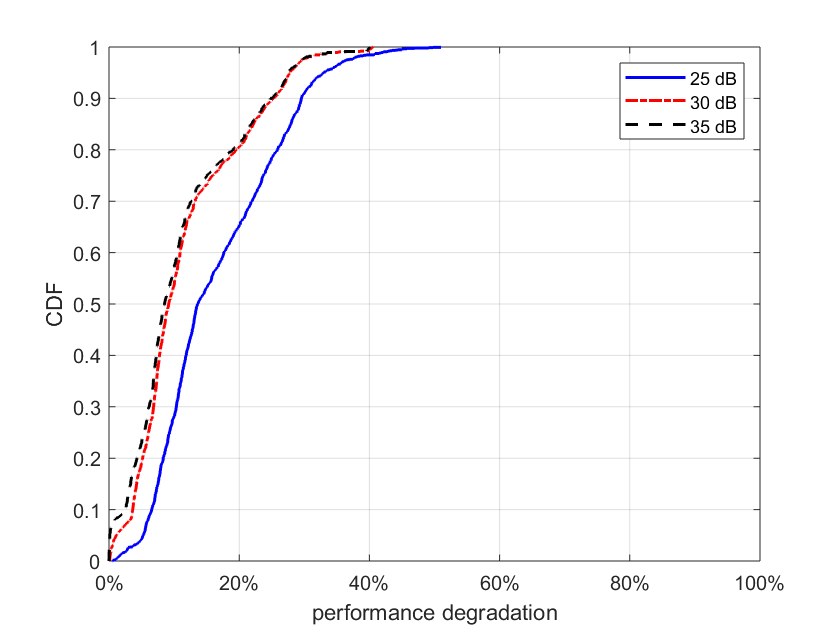

figure;
h(1,1) = cdfplot(percentageData5);hold on;
h(1,2) = cdfplot(percentageData10);
h(1,3) = cdfplot(percentageData15);
% h(1,4) = cdfplot(percentageData15);
% h(1,5) = cdfplot(percentageData20);

set( h(1,1), 'LineStyle', '-', 'Color', 'b','LineWidth',1.5);
xtickformat('percentage');
xlim([0 100]);
set( h(1,2), 'LineStyle', '-.', 'Color', 'r','LineWidth',1.5);
set( h(1,3), 'LineStyle', '--', 'Color', 'k','LineWidth',1.5);
% set( h(1,4), 'LineStyle', ':', 'Color', 'k','LineWidth',1.5);
% set( h(1,5), 'LineStyle', '-', 'Color', 'k','LineWidth',.5);
% hopNumCount_0 = [];
% hopNumCount_1 = [];
% hopNumCount_2 = [];
% hopNumCount_3 = [];
% hopNumCount_4 = [];
% for i = 1:length(name_2_9)
%     filename = pathname + name_2_9(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
%     hopNumCount_0 = [hopNumCount_0, sum(data(2,:)==0)];
%     hopNumCount_1 = [hopNumCount_1, sum(data(2,:)==1)];
%     hopNumCount_2 = [hopNumCount_2, sum(data(2,:)==2)];
%     hopNumCount_3 = [hopNumCount_3, sum(data(2,:)==3)];
%     hopNumCount_4 = [hopNumCount_4, sum(data(2,:)==4)];
% end
% hopNumCount_0 = hopNumCount_0'./pathNum_name_2_9;
% hopNumCount_1 = hopNumCount_1'./pathNum_name_2_9;
% hopNumCount_2 = hopNumCount_2'./pathNum_name_2_9;
% hopNumCount_3 = hopNumCount_3'./pathNum_name_2_9;
% hopNumCount_4 = hopNumCount_4'./pathNum_name_2_9;
% h(2,1) = cdfplot(hopNumCount_0');hold on;
% h(2,2) = cdfplot(hopNumCount_1');
% h(2,3) = cdfplot(hopNumCount_2');
% h(2,4) = cdfplot(hopNumCount_3');
% h(2,5) = cdfplot(hopNumCount_4');
% set( h(2,1), 'LineStyle', '-', 'Color', 'b','LineWidth',1.5);
% set( h(2,2), 'LineStyle', '-.', 'Color', 'g','LineWidth',1.5);
% set( h(2,3), 'LineStyle', '--', 'Color', 'r','LineWidth',1.5);
% set( h(2,4), 'LineStyle', ':', 'Color', 'c','LineWidth',1.5);
legend('25 dB','30 dB', '35 dB');
% legend('1-hop, low density','2-hop, low density','3-hop, low density','4-hop, low density',...
%     '5-hop, low density','1-hop, high density','2-hop, high density','3-hop, high density','4-hop, high density','5-hop, high density');
title '';
xlabel('performance degradation');
ylabel('CDF');

% annotation('textarrow',[0.6214 0.5553],[0.5786 0.5786],'String','')
% annotation('textarrow',[0.3554 0.4018],[0.6333 0.6333],'String','')
% annotation('textarrow',[0.1571 0.2054],[0.6762 0.6762],'String','')

PathResult1Mbs300m = '../../Data/Throughput_Comparison/Single_MBS/300/Downlink/';
% PathResult2Mbs300m = '../../Data/Paths/Double_MBS/300/';
% PathResult1MbsLA = '../../Data/Paths/Single_MBS_LimitedArea/200/';
% PathResult2MbsLA = '../../Data/Paths/Double_MBS_LimitedArea/200/';
% PathResultBench = '../../Data/Paths/Idp/';

Data = ReadThroughputComparisonData(PathResult1Mbs300m);


## Get the percentage information

percentageData0 = Data(1:100,1:25,3);
percentageData0 = reshape(percentageData0,1,100*25);
percentageData0 = percentageData0(percentageData0~=0).*100;
oldThData0 = Data(1:100,1:25,1);
oldThData0 = reshape(oldThData0,1,100*25);
oldThData0 = oldThData0(oldThData0~=0);
avg_OldThData0 = mean(oldThData0);
newThData0 = Data(1:100,1:25,2);
newThData0 = reshape(newThData0,1,100*25);
newThData0 = newThData0(newThData0~=0);
avg_NewThData0 = mean(newThData0);

percentageData5 = Data(101:200,1:25,3);
percentageData5 = reshape(percentageData5,1,100*25);
percentageData5 = percentageData5(percentageData5~=0).*100;
oldThData5 = Data(101:200,1:25,1);
oldThData5 = reshape(oldThData5,1,100*25);
oldThData5 = oldThData5(oldThData5~=0);
avg_OldThData5 = mean(oldThData5);
newThData5 = Data(101:200,1:25,2);
newThData5 = reshape(newThData5,1,100*25);
newThData5 = newThData5(newThData5~=0);
avg_NewThData5 = mean(newThData5);

percentageData10 = Data(201:300,1:25,3);
percentageData10 = reshape(percentageData10,1,100*25);
percentageData10 = percentageData10(percentageData10~=0).*100;
oldThData10 = Data(201:300,1:25,1);
oldThData10 = reshape(oldThData10,1,100*25);
oldThData10 = oldThData10(oldThData10~=0);
avg_OldThData10 = mean(oldThData10);
newThData10 = Data(201:300,1:25,2);
newThData10 = reshape(newThData10,1,100*25);
newThData10 = newThData10(newThData10~=0);
avg_NewThData10 = mean(newThData10);

percentageData15 = Data(301:400,1:25,3);
percentageData15 = reshape(percentageData15,1,100*25);
percentageData15 = percentageData15(percentageData15~=0).*100;
oldThData15 = Data(301:400,1:25,1);
oldThData15 = reshape(oldThData15,1,100*25);
oldThData15 = oldThData15(oldThData15~=0);
avg_OldThData15 = mean(oldThData15);
newThData15 = Data(301:400,1:25,2);
newThData15 = reshape(newThData15,1,100*25);
newThData15 = newThData15(newThData15~=0);
avg_NewThData15 = mean(newThData15);

percentageData20 = Data(401:500,1:25,3);
percentageData20 = reshape(percentageData20,1,100*25);
percentageData20 = percentageData20(percentageData20~=0).*100;
oldThData20 = Data(401:500,1:25,1);
oldThData20 = reshape(oldThData20,1,100*25);
oldThData20 = oldThData20(oldThData20~=0);
avg_OldThData20 = mean(oldThData20);
newThData20 = Data(401:500,1:25,2);
newThData20 = reshape(newThData20,1,100*25);
newThData20 = newThData20(newThData20~=0);
avg_NewThData20 = mean(newThData20);

## Get the distribution of hop number of each logical link

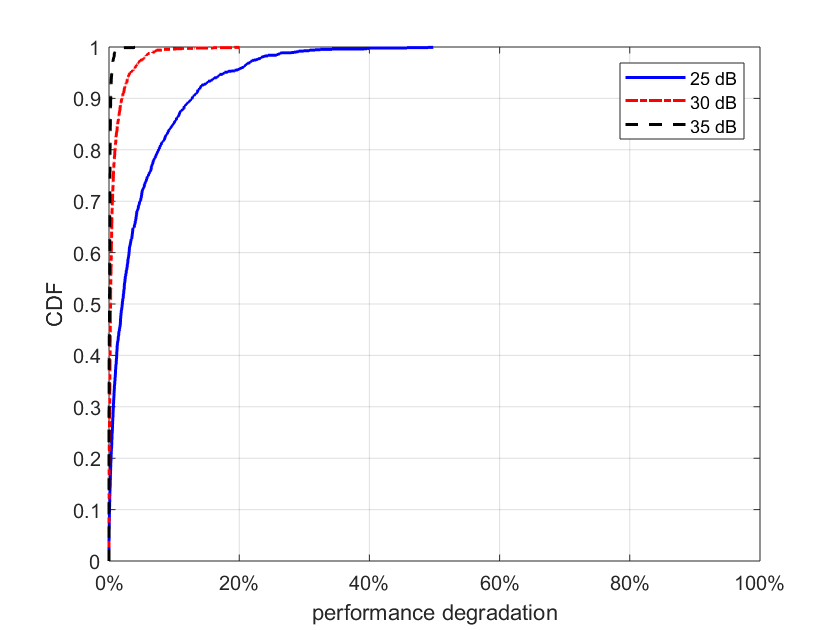

figure;
h(1,1) = cdfplot(percentageData5);hold on;
h(1,2) = cdfplot(percentageData10);
h(1,3) = cdfplot(percentageData15);
% h(1,4) = cdfplot(percentageData15);
% h(1,5) = cdfplot(percentageData20);

set( h(1,1), 'LineStyle', '-', 'Color', 'b','LineWidth',1.5);
xtickformat('percentage');
xlim([0 100]);
set( h(1,2), 'LineStyle', '-.', 'Color', 'r','LineWidth',1.5);
set( h(1,3), 'LineStyle', '--', 'Color', 'k','LineWidth',1.5);
% set( h(1,4), 'LineStyle', ':', 'Color', 'k','LineWidth',1.5);
% set( h(1,5), 'LineStyle', '-', 'Color', 'k','LineWidth',.5);
% hopNumCount_0 = [];
% hopNumCount_1 = [];
% hopNumCount_2 = [];
% hopNumCount_3 = [];
% hopNumCount_4 = [];
% for i = 1:length(name_2_9)
%     filename = pathname + name_2_9(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
%     hopNumCount_0 = [hopNumCount_0, sum(data(2,:)==0)];
%     hopNumCount_1 = [hopNumCount_1, sum(data(2,:)==1)];
%     hopNumCount_2 = [hopNumCount_2, sum(data(2,:)==2)];
%     hopNumCount_3 = [hopNumCount_3, sum(data(2,:)==3)];
%     hopNumCount_4 = [hopNumCount_4, sum(data(2,:)==4)];
% end
% hopNumCount_0 = hopNumCount_0'./pathNum_name_2_9;
% hopNumCount_1 = hopNumCount_1'./pathNum_name_2_9;
% hopNumCount_2 = hopNumCount_2'./pathNum_name_2_9;
% hopNumCount_3 = hopNumCount_3'./pathNum_name_2_9;
% hopNumCount_4 = hopNumCount_4'./pathNum_name_2_9;
% h(2,1) = cdfplot(hopNumCount_0');hold on;
% h(2,2) = cdfplot(hopNumCount_1');
% h(2,3) = cdfplot(hopNumCount_2');
% h(2,4) = cdfplot(hopNumCount_3');
% h(2,5) = cdfplot(hopNumCount_4');
% set( h(2,1), 'LineStyle', '-', 'Color', 'b','LineWidth',1.5);
% set( h(2,2), 'LineStyle', '-.', 'Color', 'g','LineWidth',1.5);
% set( h(2,3), 'LineStyle', '--', 'Color', 'r','LineWidth',1.5);
% set( h(2,4), 'LineStyle', ':', 'Color', 'c','LineWidth',1.5);
legend('25 dB','30 dB', '35 dB');
% legend('1-hop, low density','2-hop, low density','3-hop, low density','4-hop, low density',...
%     '5-hop, low density','1-hop, high density','2-hop, high density','3-hop, high density','4-hop, high density','5-hop, high density');
title '';
xlabel('performance degradation');
ylabel('CDF');

% annotation('textarrow',[0.6214 0.5553],[0.5786 0.5786],'String','')
% annotation('textarrow',[0.3554 0.4018],[0.6333 0.6333],'String','')
% annotation('textarrow',[0.1571 0.2054],[0.6762 0.6762],'String','')

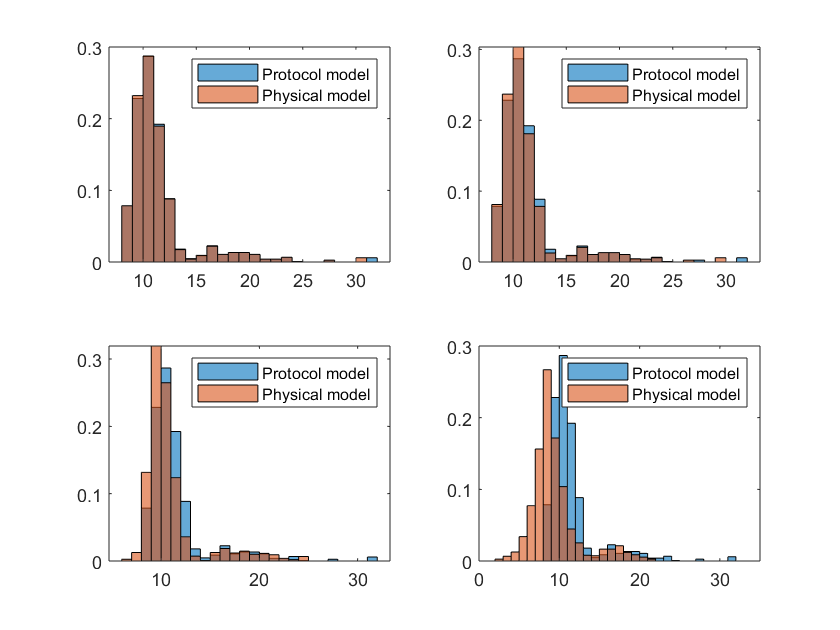

figure;
subplot(2,2,4);
histogram(oldThData0,'Normalization','probability'); hold on;
histogram(newThData0,'Normalization','probability');
xlim([0 35])
legend('Protocol model', 'Physical model');
subplot(2,2,3);
histogram(oldThData5,'Normalization','probability'); hold on;
histogram(newThData5,'Normalization','probability');
legend('Protocol model', 'Physical model');
subplot(2,2,2);
histogram(oldThData10,'Normalization','probability'); hold on;
histogram(newThData10,'Normalization','probability');
legend('Protocol model', 'Physical model');
subplot(2,2,1);
histogram(oldThData15,'Normalization','probability'); hold on;
histogram(newThData15,'Normalization','probability');
legend('Protocol model', 'Physical model');